# LAB4 MATLAB Programming

李志颖 12210309  夏琮杰12210520

## Introduction

1.Using Matlab to calculate the approximation of Continuous-time Fourier Transform

2.Using abs and angle to calculate the magnitude and the phase of the signal.

3. Using lsim(b,a,x,t) to calculate the output of the differential system

4.Using freqs(b,a,w) = H to calculate the frequency response of the system

5.Using X = tua * fft(x) to calculate X(jw) 

## Results and analysis

## 4.2

### (a)

Let 

    
$$X\left(t\right)=e^{-2|t|} =g\left(t\right)+g\left(-t\right)=e^{-2t} u\left(t\right)+e^{2t} u\left(-2t\right)$$


The Fourier Transform for X(t) is

    
$$X\left(\textrm{jw}\right)=\frac{1}{2+\textrm{jw}}+\frac{1}{2-\textrm{jw}}$$


### (b)

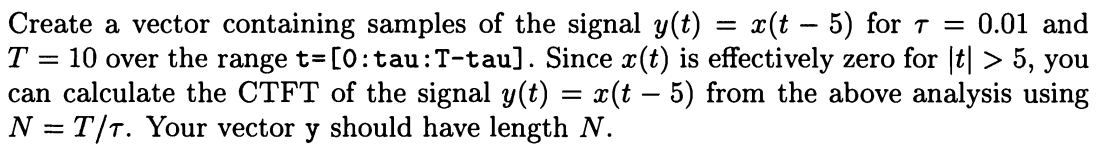


$$Y\left(\textrm{jw}\right)=e^{\textrm{jw}\left(-5\right)} X\left(\textrm{jw}\right)=\frac{e^{\textrm{jw}\left(-5\right)} }{2+\textrm{jw}}+\frac{e^{\textrm{jw}\left(-5\right)} }{2-\textrm{jw}}$$


tau = 0.01;
T = 10;
t = 0:tau:T-tau;
N = T / tau;
x = exp(-2 * t) .* heaviside(t) + exp(2 * t) .* heaviside(-t);
y = exp(-2 * (t - 5)) .* heaviside(t - 5) + exp(2 * (t - 5)) .* heaviside(-(t - 5));
N

N = 1000

### (c)

It outputs a coefficient that has been fftshifted, when the zero frequency would be in the middle of the Y sequence.

Y = fftshift(tau*fft(y));

### (d)

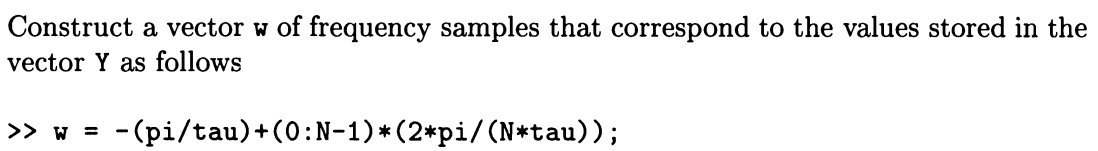

w = -(pi / tau) + (0: N - 1) * (2 * pi / (N * tau));

### (e)

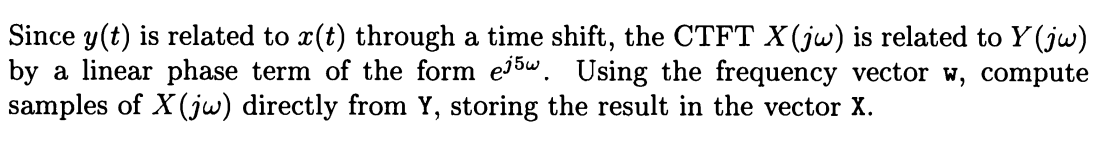

y(t) = x(t-5) shifted 5 units to the right, So the time domain signal obtained by shifting y(t) left by 5 units is the answer we need to ask for.We just need to multiply inside the frequency domain by a $e^{\textrm{j5w}}$

X = exp(-1j*5*w).*Y;

### (f)

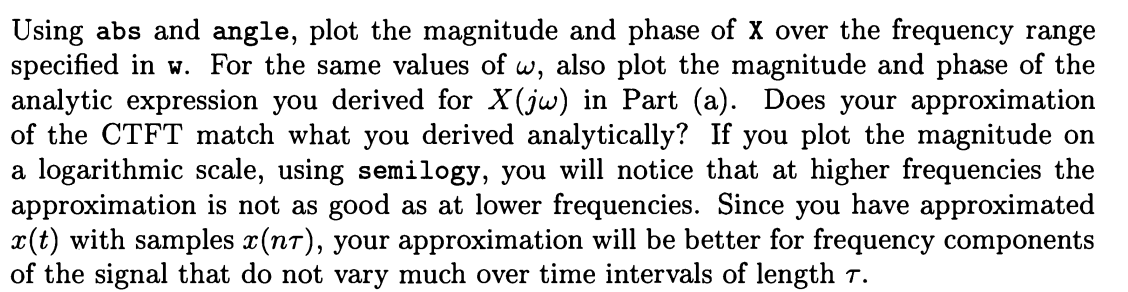

plot

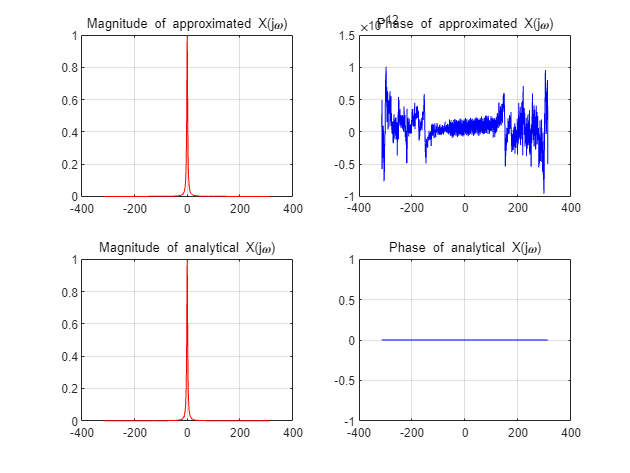

X_analytic = 1 ./ (2 + 1j * w) + 1 ./ (2 - 1j * w);

figure
subplot(2,2,1)
plot(w,abs(X),'r');
title('Magnitude of approximated X(j\omega)');
grid on;
subplot(2,2,2)
plot(w, angle(X), 'b')
title('Phase of approximated X(j\omega)')
grid on;
subplot(2,2,3)
plot(w, abs(X_analytic), 'r')
title('Magnitude of analytical X(j\omega)')
grid on;
subplot(2,2,4)
plot(w, angle(X_analytic), 'b')
title('Phase of analytical X(j\omega)')
grid on;

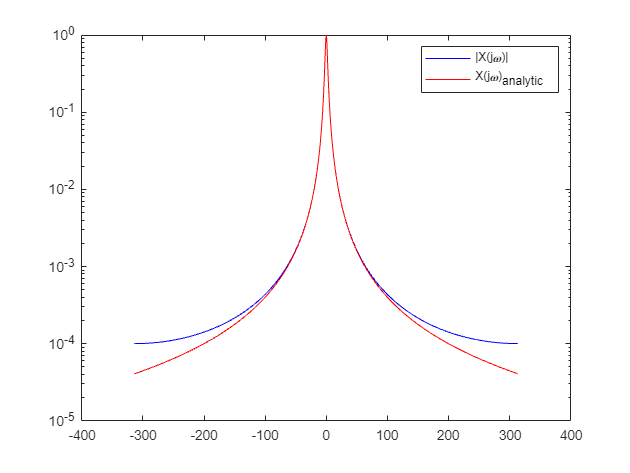

figure
semilogy(w,abs(X),'b')
hold on
semilogy(w,abs(X_analytic),'r')
hold off
legend('|X(j\omega)|','X(j\omega)_{analytic}')

The difference between the value of X and the resolved value is relatively large in the high-frequency region.

The CTFT provides a more accurate description of frequency components that do not vary much in the tau interval, but the analysis of high frequencies suffers from large errors.

### (g)

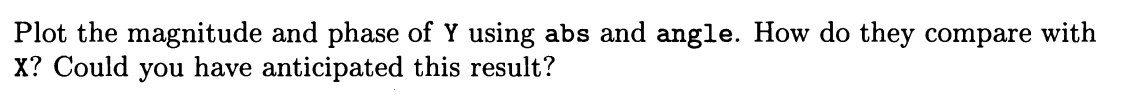

Plot the phase and amplitude of Y against X

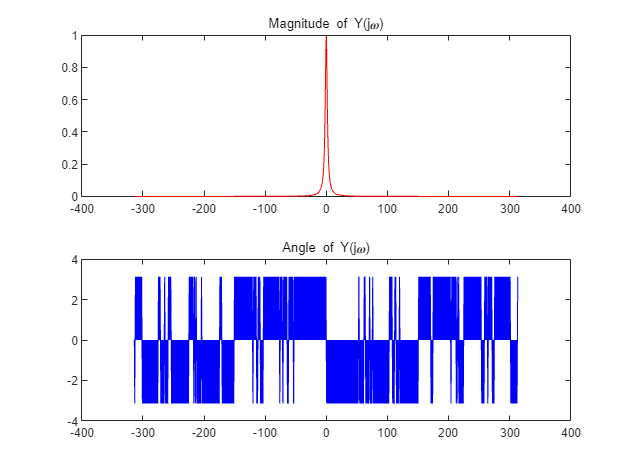

figure
subplot(2, 1, 1)
plot(w, abs(Y), 'r')
title('Magnitude of Y(j\omega)')
subplot(2, 1, 2)
plot(w, angle(Y), 'b')
title('Angle of Y(j\omega)')

X and Y are the same in magnitude nut distinct in phase.That is because the time shifting was reflected as a phase shifting in frequency domain.

## 4.6

clear;clc;
load lab4\ctftmod.mat
who


您的变量为:

af    bf    dash  dot   f1    f2    t     x     



### (a)

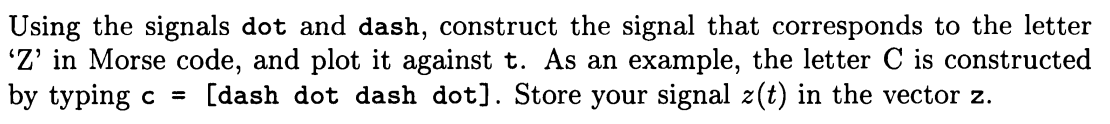

Write simple morse code using the material provided in the title

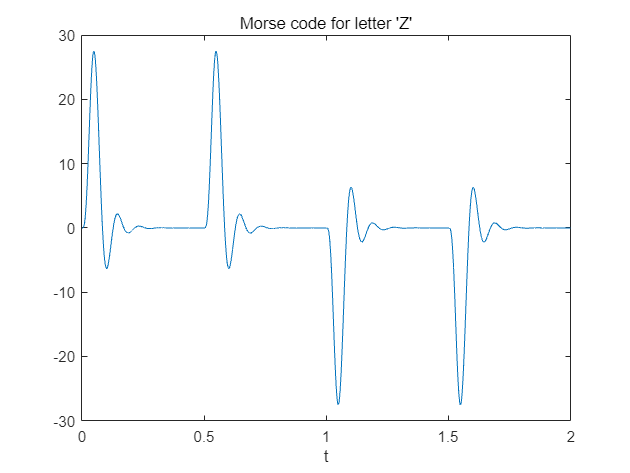

z = [dash dash dot dot];
figure 
plot(t,z);
title("Morse code for letter 'Z'")
xlabel("t");

### (b）

plot

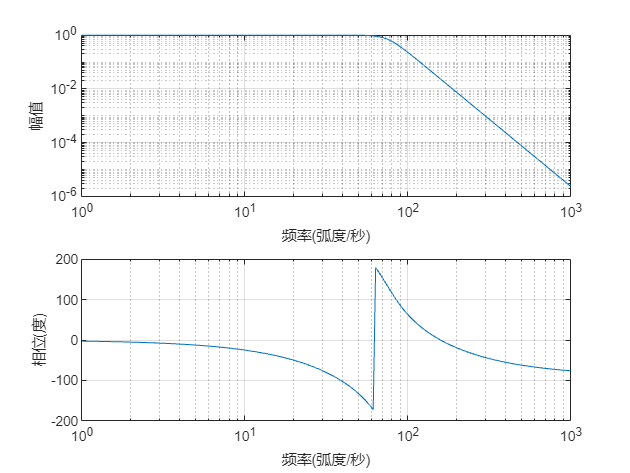

freqs(bf,af)

### (c)

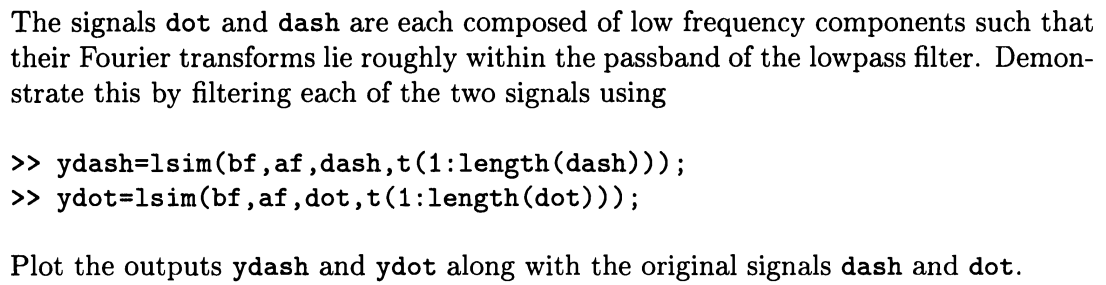

Input the dot and dash signals into the low-pass filter and observe the waveforms.

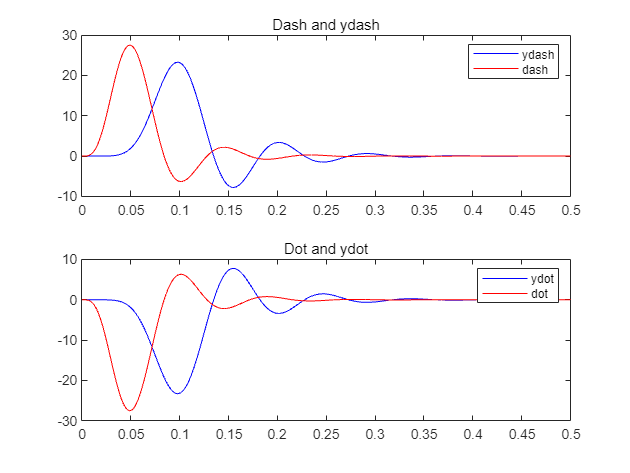

ydash = lsim(bf, af, dash, t(1: length(dash)));
ydot = lsim(bf, af, dot, t(1: length(dot)));

figure
subplot(2, 1, 1)
plot(t(1: length(dash)), ydash, 'b')
hold on;
plot(t(1: length(dash)), dash, 'r')
title('Dash and ydash')
legend('ydash', 'dash')
subplot(2, 1, 2)
plot(t(1: length(dot)), ydot, 'b')
hold on
plot(t(1: length(dot)), dot, 'r')
title('Dot and ydot')
legend('ydot', 'dot')
hold on
plot(t(1: length(dot)), dot, 'r')
title('Dot and ydot')
legend('ydot', 'dot')

### (d)

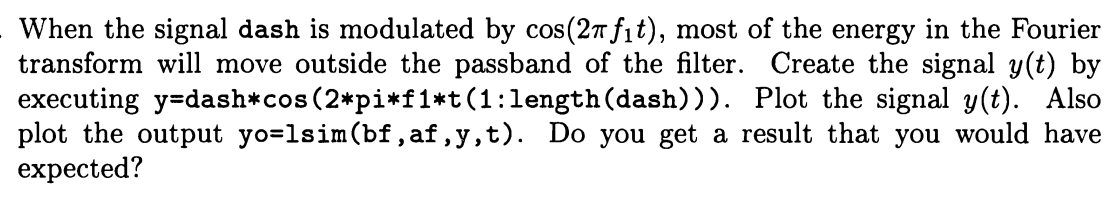

The dot signal is modulated with the frequency f1, while the modulated signal is fed into a low-pass filter. The two outputs are visualised using the plot function

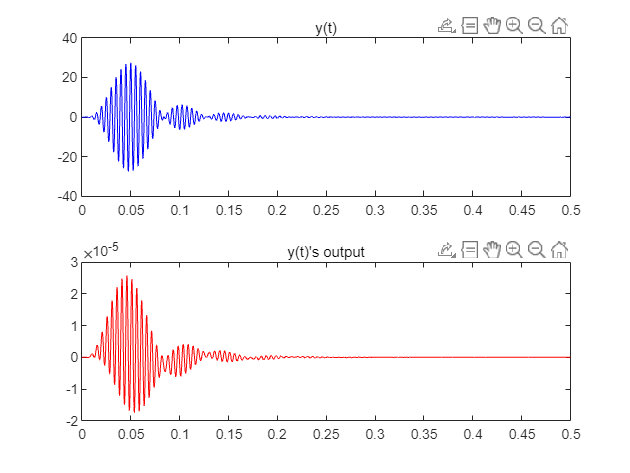

y = dash .* cos(2 * pi* f1 * t(1: length(dash)));
yo = lsim(bf, af, y, t(1: length(dash)));

figure
subplot(2, 1, 1)
plot(t(1: length(dash)), y, 'b')
title('y(t)')
subplot(2, 1, 2)
plot(t(1: length(dash)), yo, 'r')
title('y(t)''s output')

As can be seen in the figure, the waveform of the modulated dot signal is basically the same before and after passing through the filter, but the energy is greatly compressed after passing through the low-pass filter.

### (e)

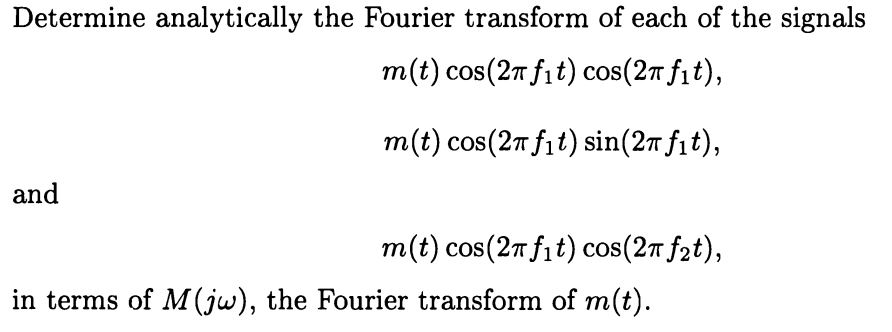


$$Y_1 \left(j\omega \right)=\frac{1}{2}\left(\frac{1}{2}M\left\lbrack j\left(\omega -4\pi f_1 \right)\right\rbrack +\frac{1}{2}M\left(j\omega \right)\right)+\frac{1}{2}\left(\frac{1}{2}M\left(j\omega \right)+\frac{1}{2}M\left\lbrack j\left(\omega +4\pi f_1 \right)\right\rbrack \right)=\frac{1}{4}M\left\lbrack j\left(\omega -4\pi f_1 \right)\right\rbrack +\frac{1}{2}M\left(j\omega \right)+\frac{1}{4}M\left\lbrack \left(j\left(\omega +4\pi f_1 \right)\right)\right\rbrack$$



$$Y_2 \left(j\omega \right)=\frac{1}{2j}\left(\frac{1}{2}M\left\lbrack j\left(\omega -4\pi f_1 \right)\right\rbrack +\frac{1}{2}M\left(j\omega \right)\right)-\frac{1}{2j}\left(\frac{1}{2}M\left(j\omega \right)+\frac{1}{2}M\left\lbrack j\left(\omega +4\pi f_1 \right)\right\rbrack \right)=\frac{1}{4j}M\left\lbrack j\left(\omega -4\pi f_1 \right)\right\rbrack -\frac{1}{4j}M\left\lbrack \left(j\left(\omega +4\pi f_1 \right)\right)\right\rbrack$$



$$\begin{array}{l}
Y_3 \left(j\omega \right)=\frac{1}{2}\left(\frac{1}{2}M\left\lbrack j\left(\omega -2\pi f_{1-} 2\pi f_2 \right)\right\rbrack +\frac{1}{2}M\left(\left\lbrack j\left(\omega -2\pi f_{1+} 2\pi f_2 \right)\right\rbrack \right)\right)+\frac{1}{2}\left(\frac{1}{2}M\left(j\left(\omega +2\pi f_{1-} 2\pi f_2 \right)\right)+\frac{1}{2}M\left\lbrack j\left(\omega +2\pi +2\pi f_2 \right)\right\rbrack \right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\frac{1}{4}M\left\lbrack j\left(\omega -2\pi f_{1-} 2\pi f_2 \right)\right\rbrack +\frac{1}{4}M\left\lbrack j\left(\omega -2\pi f_{1+} 2\pi f_2 \right)\right\rbrack +\frac{1}{4}M\left\lbrack j\left(\omega +2\pi f_{1-} 2\pi f_2 \right)\right\rbrack +\frac{1}{4}M\left\lbrack j\left(\omega +2\pi f_{1+} 2\pi f_2 \right)\right\rbrack 
\end{array}$$


### (f)

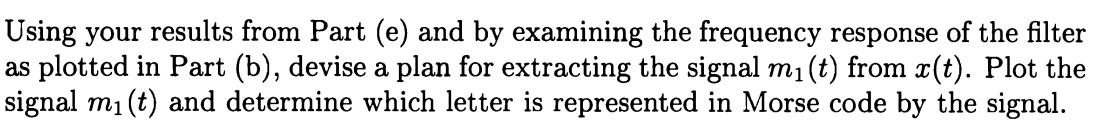

Demodulate the m1 component of the x signal. Since the modulating signal of m1 is a cos-type signal of f1, the demodulation should be done by using the same cos-type signal of f1 to re-translate the original signal to the origin. The components of the signal that are at the origin are low frequency signals and can be passed through the filter given in the title. Note that the demodulated signal is fed into the filter and multiplied by two to return the energy lost in the demodulation process

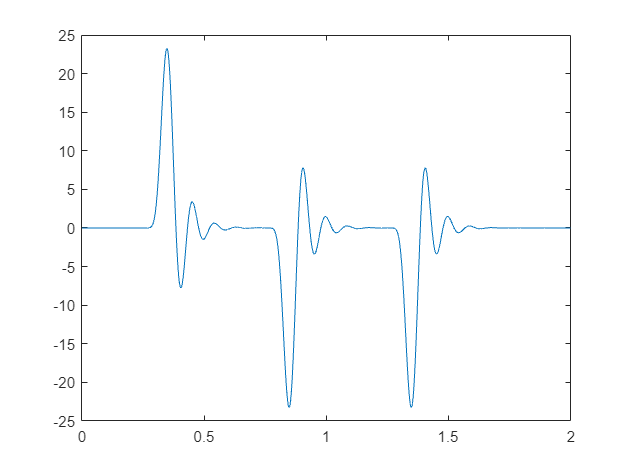

figure
m1=2*lsim(bf,af,x.*cos(2*pi*f1*t),t);
plot(t,m1);

According to the given table , we can know that the letter 1 is 'D'

### (g)

same as (f)

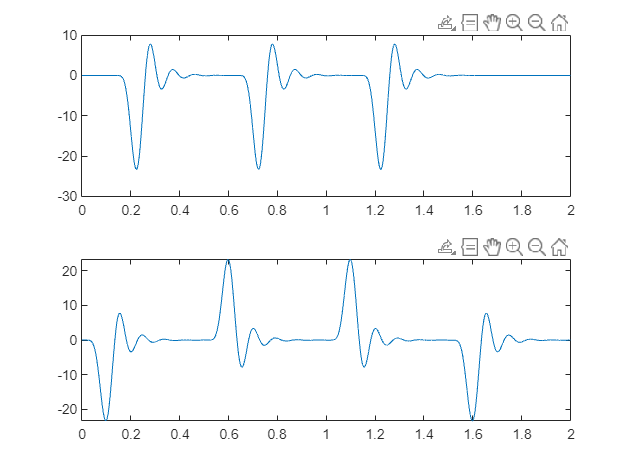

figure
subplot(2,1,1)
m2=2*lsim(bf,af,x.*sin(2*pi*f2*t),t);
plot(t,m2);
subplot(2,1,2)
m3=2*lsim(bf,af,x.*sin(2*pi*f1*t),t);
plot(t,m3);

According to the given table , we can know that the letter 2 is 's', the letter 3 is 'P'

the final answer is 'DSP'(Digital Signal Processing)--数字信号处理

## Experience

李志颖12210309

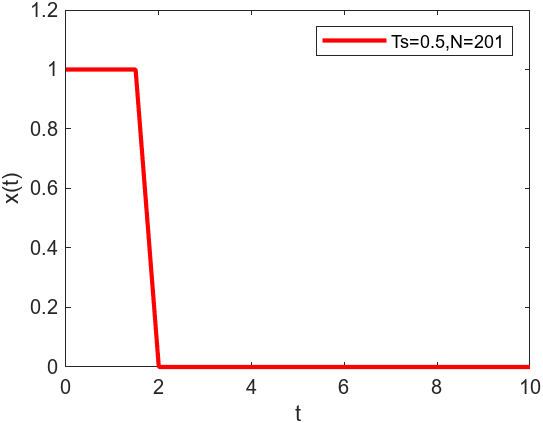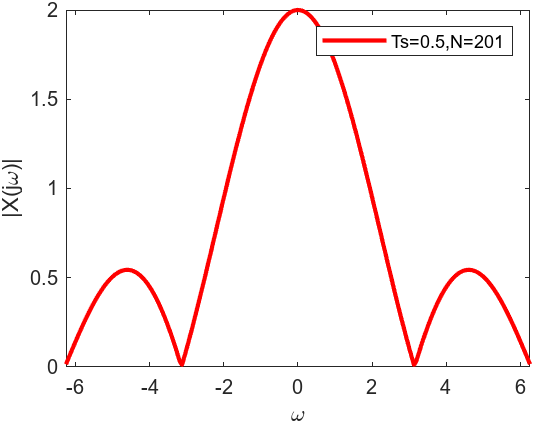

夏琮杰12210520

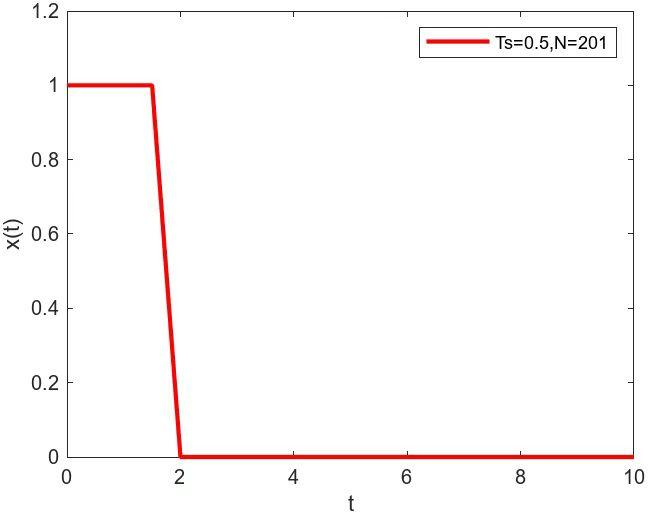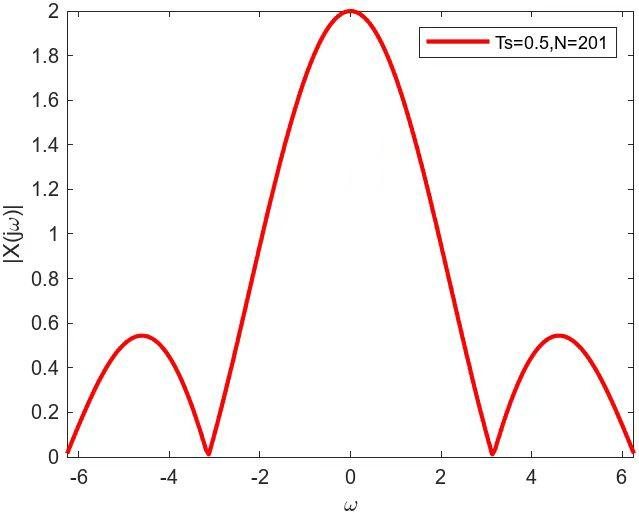

1.In 4.6, it's fun to use what you've learnt to decode Morse Code!

2.Reading the book carefully before solving the problem.

## self—scoring

100